# 核磁共振 T2 反演

## 共轭梯度法

% 正演模型：三指数模型
clear;clc;close all;
% 基本参数
M = 3000;         
N = 100;       
Te = 0.3;
binset = logspace(-1, 4, N)';
t = Te*(1:M)';
% 正演回波衰减曲线
bin = [5, 50, 200];
Amp = [0.3, 0.5, 0.2];
echo = Amp(1)*exp(-t/bin(1)) + Amp(2)*exp(-t/bin(2)) + Amp(3)*exp(-t/bin(3));
%系数矩阵
A = zeros(M, N);
for i = 1:M
    for j = 1:N
        A(i, j) = exp(-t(i)/binset(j));
    end
end
% 回波加噪反演
per = 0.05;
noise = per*randn(M,1);
echo = echo + noise;
snr = echo(1)/(norm(noise)/sqrt(M-1))

snr = 19.4884

T2 = CGNE(A, echo, 1000);
totalT2 = sum(T2)

totalT2 = 1.0794

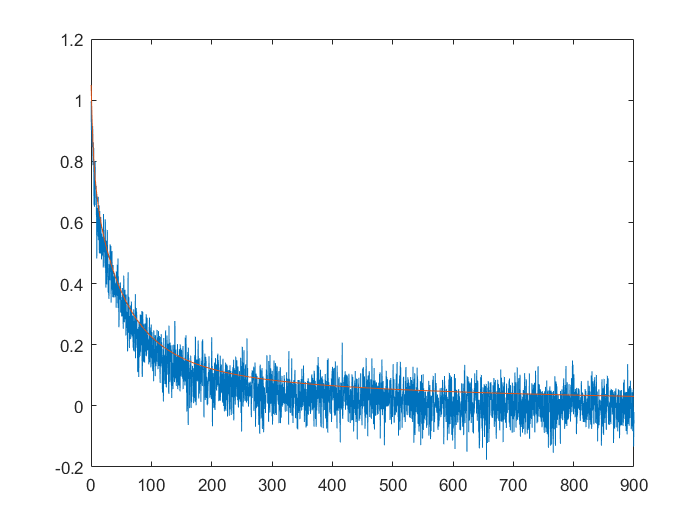

% 拟合误差
y = A*T2;
ERR = norm(echo - y)/sqrt(M-1);
% 结果显示
figure;
plot(t, echo, t, y);

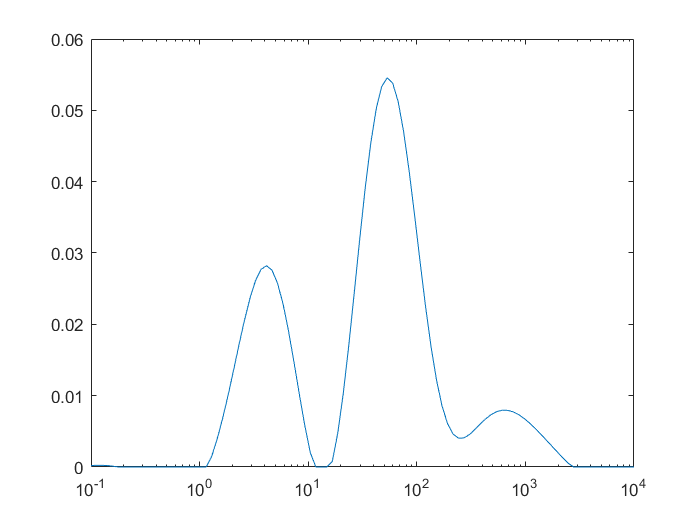

figure;
semilogx(binset, T2);

function X=CGNE(A, b, km)
% A --- parameter matrix
% b --- measured data
% X  --- return inversion result
% km --- iteration times, default,km=1000 
% initial value
N = size(A,2);
i = 0;
err = 1e-6;
x = zeros(N,1);
r = b - A*x;
d0 = A'*r;
% 迭代
while norm(r)/norm(b) > err && i < km
    alpha = norm(A'*r)^2 / norm(A*d0)^2;
    x = x + alpha*d0;
    r = r - alpha*A*d0;
    d = A'*r;
    beta = norm(d)^2 / norm(d0)^2;
    d = d + beta*d0;
    d0 = d;
    i = i+1;
end
x(x < 0) = 0;
X = x;
end